# Integrate AI Model into Simulink for Battery State of Charge Estimation

This example shows how to integrate a deep neural network into Simulink® for for battery state of charge (SOC) estimation. 

SOC is the level of charge of an electric battery relative to its capacity, measured as a percentage. This example integrates a trained deep neural network for battery SOC estimation into Simulink®.

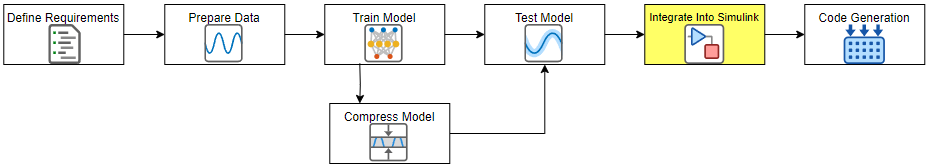

This example is part of a series of examples that take you through a battery state of charge estimation workflow. You can run each step independently or work through the steps in order. This example follows the [Test Model for Battery State of Charge Estimation](docid:nnet_ug#mw_c18d3899-e7de-487f-a2a6-9e91378ecb1e) example. For more information about the full workflow, see [Battery State of Charge Estimation Using Deep Learning](docid:nnet_ug#mw_a7c8375f-dbb8-49d8-aa9c-a55a2cf7be25). test

## Load Trained Network

If you have run the previous steps, then the example uses the network that you trained. Otherwise, the example loads a network trained as in [Train Network for Battery State of Charge Estimation](docid:nnet_ug#mw_0e7f3ac5-d252-4333-a2cd-cbc2bae0dc2a) and compressed in [Compress Network for Battery State of Charge Estimation](docid:nnet_ug#mw_1b5a5fa9-fc8b-434b-936c-6ce1e74b8f32).

if ~exist("recurrentNet","var")
    load("pretrainedBSOCNetworkCompressed.mat")
end

The network has been trained to predict battery SOC given three inputs: temperature, voltage, and current. The network was trained on data taken at four different ambient temperatures: -10, 0, 10, and 25 degrees Celsius. 

## Export Network to Simulink

Export the trained neural network to Simulink® using the `exportNetworkToSimulink` function. This function converts the network into layer blocks. You can use layer blocks to: 

- Visualize the operations of each layer in a network. 

- Easily debug issues with a Simulink model and generated code.

- Customized generated code using built-in Simulink® features. 

The `exportNetworkToSimulink` function creates a Simulink® model, `my_model`, with an input port, a Layer Blocks subsystem, and an output port.

exportNetworkToSimulink(recurrentNet);

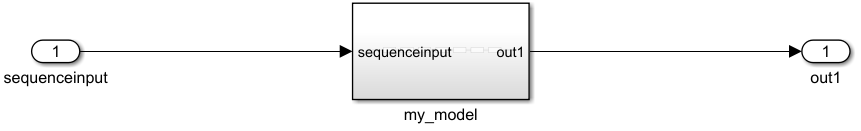

The subsystem `my_model` contains the neural network described using layer blocks. Click inside the subsystem to see the layer blocks. If you have not compressed your network, then you will see slightly different blocks. Each block represents a layer.

To see the internal operations of each layer block, click the down arrow.

## Integrate Network into Simulink Model

Open a Simulink model that simulates battery state of charge. This model has a placeholder Layer Blocks subsystem inside the SOC Estimator subsystem.

open_system("BatterySOCEstimationDeepLearning")

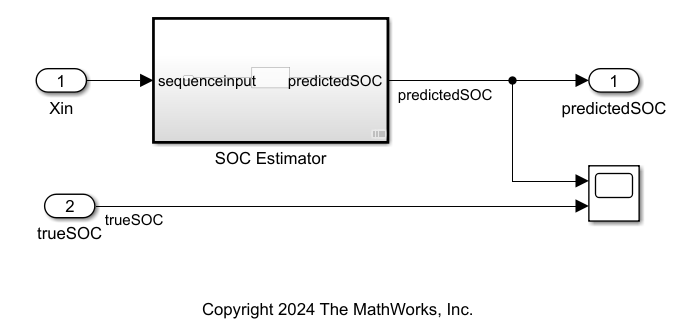

Copy the generated Layer Blocks subsystem, `my_model`, paste it inside the SOC Estimator subsystem, and connect the input and output ports. 

### Simulate Using Test Data

Load the test data for one temperature.

testData = load("BSOCTestingData\BSOC_" + "0" + "_degrees.mat");

Normalize the test data using the training statistics.

load("BSOCTrainingMaxMinStats","maxX","minX");
testData.X = rescale(testData.X,InputMin=minX,InputMax=maxX);

Extract the number of features and the length of the data.

numFeatures = size(testData.X,2);
steps = size(testData.X,1);

Create a variable `Ts` that controls the step size. Create a `timeseries` object to use in the Simulink model.

Ts = 1;
timeVector = (0:Ts:(steps-1))';
Xin = timeseries(testData.X(:,1:numFeatures), timeVector);
trueSOC = timeseries(testData.Y, timeVector);

Create input data for the model.

ds = Simulink.SimulationData.Dataset;
ds = setElement(ds,1,Xin);
ds = setElement(ds,2,trueSOC);

Simulate the model and export the simulation output to the workspace.

in = Simulink.SimulationInput("BatterySOCEstimationDeepLearning");
in = in.setModelParameter("StopTime",'steps');
in = in.setModelParameter("FixedStep",'Ts');
in = in.setExternalInput(ds);
simOut = sim(in);

View the results in the scope.

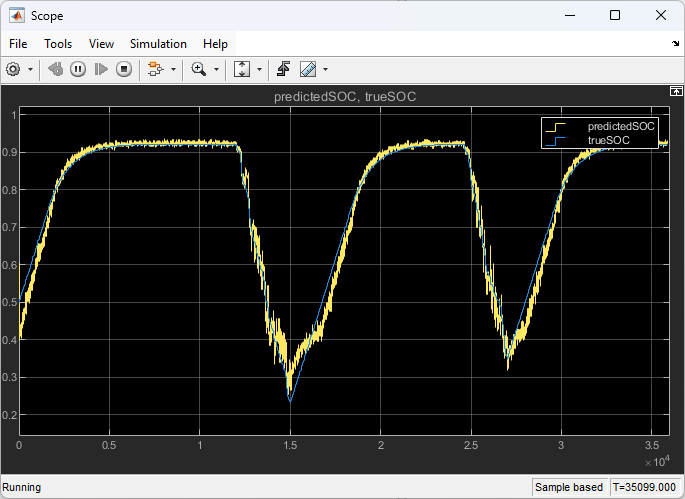

## Examine Performance Using Simulink Profiler

Simulink Profiler allows you to examine the model and block execution and to identify issues that can contribute to poor simulation performance. This process lets you see which of the layer blocks are the slowest in terms of simulation speed.

Open the Simulink model `BatterySOCEstimationDeepLearning`.

open_system("BatterySOCEstimationDeepLearning")

Start Simulink Profiler:

- On the **Debug** tab, select **Performance** > **Simulink** **Profiler**.

- On the **Profiler** tab, click **Profile**.

When the simulation is complete, the **Profiler Report** pane opens and displays the simulation profile for the model. In the **Path** column, expand **BatterySOCEstimationDeepLearning** > **SOC Estimator** > **my_model**. The pane lists the performance times of the layer blocks in descending order, from slowest to fastest.

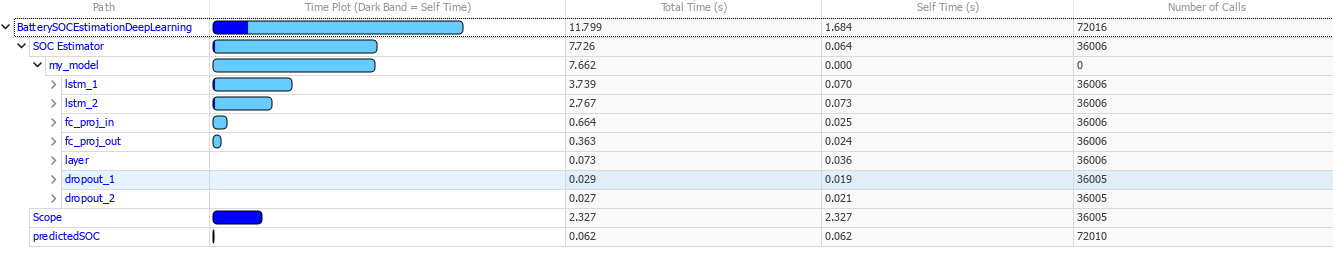

In this network, most of the inference time is spent within the two LSTM layers.

Now that the network is integrated into Simulink, you can perform software-in-the-loop (SIL) testing to check the generated code. To generate code for the model, see [Deploy Model for Battery State of Charge Estimation](docid:nnet_ug#mw_f48cbd4e-5156-468f-8ad3-0f29ef6a1642). You can also open the next example using the `openExample` function.

Optionally, if you have Requirements Toolbox™, then in the next section you can link and test system integration requirements.

## Link System Integration Requirements Using Requirements Toolbox

This section verifies the system integration requirements for the Simulink model and requires Requirements Toolbox™ and Simulink® Test™. This section does not show how to create or link requirements, only how to implement and verify the links. For more information about defining these requirements, see [Define Requirements for Battery State of Charge Estimation](docid:nnet_ug#mw_dc9e93ad-d4e8-452a-9ad2-79fba29dbd6b). For general information about how to create and manage requirements, see [Use Requirements to Develop and Verify MATLAB Functions](https://uk.mathworks.com/help/slrequirements/gs/use-requirements-to-develop-and-verify-matlab-functions.html).

Linking system integration requirements is important for ensuring the AI model behaves as expected once integrated into the Simulink model.

Check for a Requirements Toolbox license.

if ~license("test","simulink_requirements")    
    disp("This part of the example requires Requirements Toolbox.");    
    return
end

Open the system integration requirements. To add columns that indicate the implementation status and verification status of the requirements, click **Columns**   and then select **Implementation Status** and **Verification Status**. If you see a yellow banner, then click **Analyze now**. You can see each of the requirements and their implementation status and verification status. The verification status for each requirement is yellow, indicating that the status is unknown. The status turns to red if the requirement fails or green if the requirement passes. 

slreq.open("BatterySOCReqSysInt.slreqx");
sltest.testmanager.load("BatterySOCSysIntTest.mldatx");

This example has four requirements. For each ambient temperature, the RMSE for the predictions on the test data compared to the true value must be less than 0.05.

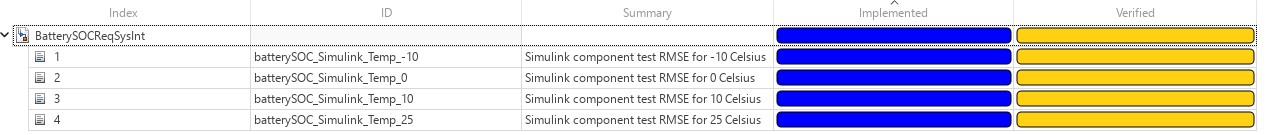

Select one of the network requirements. Each requirement is implemented by SOC Estimator subsystem and verified by a test.

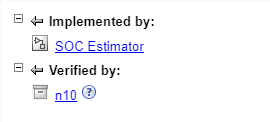

### Implement Requirements

In the previous step, you converted your deep learning model into a Simulink model. The implementation for this requirements links to the SOC Estimator subsystem. 

### Verify Requirements

The next step is to verify the requirements. To verify requirements, create tests to check the RMSE of the Simulink model predictions. You can find the system integration tests in the [`BatterySOCSysIntTest`](matlab:open('./BatterySOCSysIntTest.mldatx')) file, attached to this example as a supporting file. This file contains a test that checks for four different temperatures if the RMSE is less than 0.05. 

To run the tests, open Test Manager with [`BatterySOCSysIntTest`](matlab:open('./BatterySOCSysIntTest.mldatx')). Select `Simulink_TestData_RMSE` and click **Run**. The test passes for each temperature.

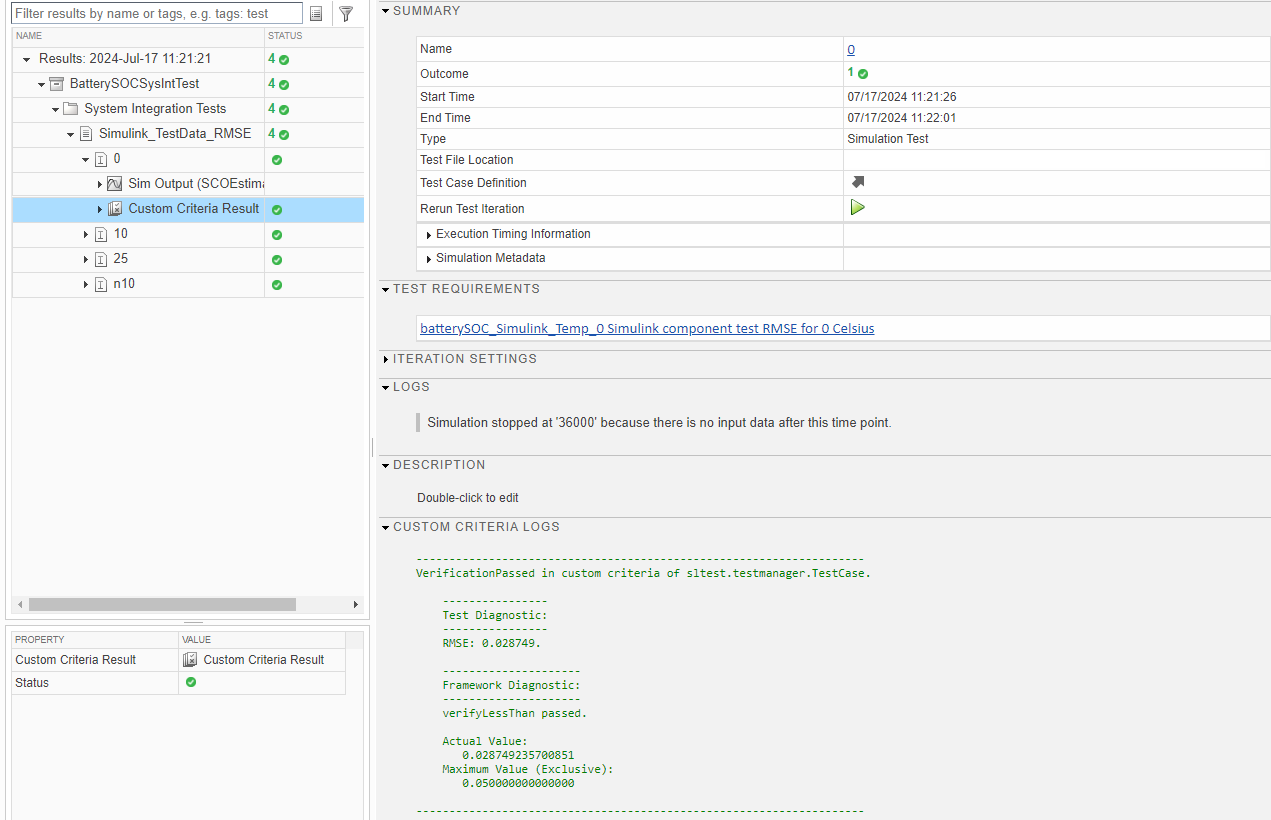

The tests check that each of the system integration requirements are met and the verification status turns to green (Passed).

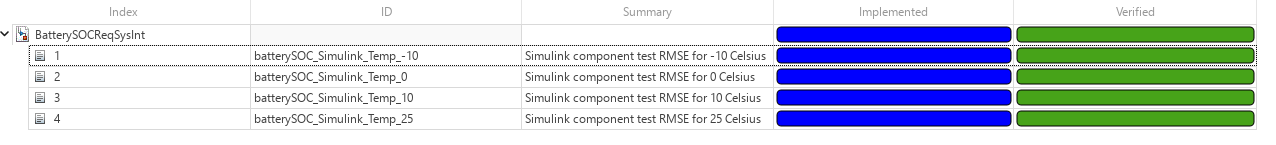

Next step: [Deploy Model for Battery State of Charge Estimation](docid:nnet_ug#mw_f48cbd4e-5156-468f-8ad3-0f29ef6a1642). You can also open the next example using the `openExample` function.

*Copyright 2024 The MathWorks, Inc.*